# Modeling and Optimizing a Battery Charging Profile

In this project, you will use MATLAB to model a battery charging profile. You will fit real lithium‑ion battery data in MATLAB, compute energy transfer through numerical integration, and analyze key performance characteristics such as charge‑rate behavior and efficiency losses.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Given data for a lithium-ion battery charging profile, use MATLAB to fit the equation for voltage provided in the Project Description.

- Plot the following curves: voltage vs. time, current vs. time, and power vs. time.

- Use integration to compute the total energy delivered to the battery (area under power-time curve).

- Analyze the rate of voltage change at different intervals (calculate derivatives), compute the time to reach 80% and 100% charge, and compute the energy lost due to resistance.

## Break Down the Problem

In the space below, define the problem statement:

List the requirements, constraints, and success criteria for the project:

What is your proposed solution?

List the steps you will need to take to achieve your proposed solution:

What challenges do you face in the process of achieving the solution?

## Task 1: Fit the voltage equation to a lithium-ion battery profile

Given real time-series voltage data for a lithium-ion battery, use MATLAB Curve Fitting Toolbox to fit the equation $V\left(t\right)=V_{\max } \left(1-e^{-\frac{t}{\textrm{RC}}} \right)$ and model the battery charging profile as a simple RC-circuit analog.

Load MathWorks example lithium-ion batteries data by following the steps [here](https://www.mathworks.com/help/predmaint/ug/data-analysis-and-feature-extraction-for-battery-raw-cycling-data.html). The page also includes information about the dataset, how the data was recorded, and the battery's maximum voltage.

**Note**: The battery from this example dataset has been cycled to failure (charged and discharged repeatedly). For this project, you may choose to use data from a single cycle and focus only on the period of time within a cycle that the battery is being charged. The battery is fully charged at 3.6V. This example battery uses a dynamic fast charging profile, but for this project, you will attempt to model the charging profile using a simple exponential capacitor charging equation.

Then, follow the workflow outlined in the [documentation](https://www.mathworks.com/help/curvefit/fit.html) to fit the voltage equation to your selected data. Plot the data and fitted curve in the same figure and, finally, print the goodness-of-fit statistics.

% Insert your code in the spaces below (or make use of helper functions and indicate where
% they can be found). Ensure your code is well-documented.

% STEP 1
% Load the example battery dataset
dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile)
load("singleCellLifeTimeData.mat")
head(data,10000)

    Data_Point    Test_Time          DateTime          Step_Time    Step_Index    Cycle_Index      Current      Voltage    Charge_Capacity    Discharge_Capacity    Charge_Energy    Discharge_Energy       dV/dt       Internal_Resistance    Temperature
    __________    _________    ____________________    _________    __________    ___________    ___________    _______    _______________    __________________    _____________    ________________    ___________    ___________________    _________

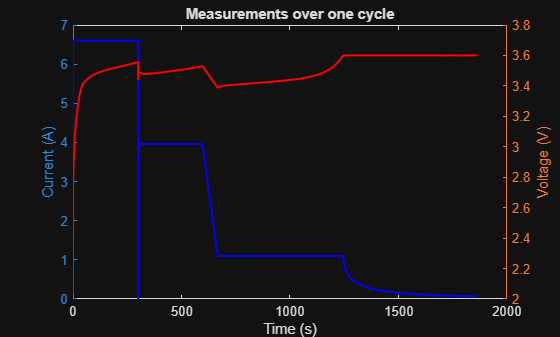


% STEP 2
% Pre-process the data to focus on a single cycle, and the period of time
% within that cycle that the battery was being charged
cycleData = data(data.Cycle_Index == 1, :); 
cycleData = cycleData(cycleData.Current > 0, :);
cycleData.DateTime = seconds(cycleData.DateTime - cycleData.DateTime(1));
figure;
yyaxis left;
plot(cycleData.DateTime,cycleData.Current, '-b', 'LineWidth', 1.5);
ylabel('Current (A)');
yyaxis right;
plot(cycleData.DateTime,cycleData.Voltage, '-r', 'LineWidth', 1.5);
ylabel('Voltage (V)');
xlabel("Time (s)");
title('Measurements over one cycle');


% STEP 3
% Follow the provided workflow to fit the voltage equation to your selected
% data. 
% Hint: Vmax is known, so the only unknown in the equation is RC (also
% known as tau, the RC time constant - it is equivalent to the time it takes
% for a capacitor to reach ~63.2% of its max voltage). When you are fitting
% the curve to the data, you are essentially estimating the unknown
% parameter, tau.

voltage = cycleData.Voltage;
time = cycleData.DateTime;
Vmax = cycleData.Voltage(end); 


ft = fittype('Vmax * (1 - exp(-time/tau))','independent', 'time','coefficients', 'tau', 'problem', 'Vmax');
[f, gof] = fit(time, voltage, ft, 'problem', Vmax);

f

f =      General model:
     f(time) = Vmax * (1 - exp(-time/tau))
     Coefficients (with 95% confidence bounds):
       tau =      0.2278  (0.2095, 0.2461)
     Problem parameters:
       Vmax =         3.6

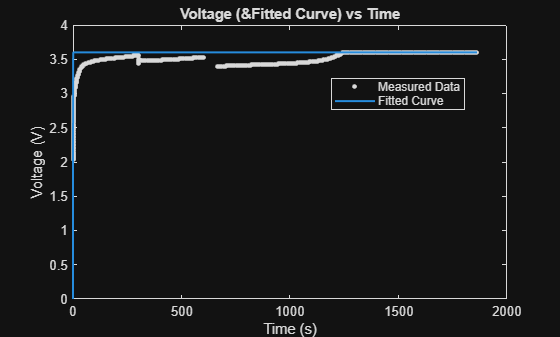


% STEP 4
% Plot the data and the fitted curve in the same figure.
figure;
plot(f, time, voltage);
xlabel("Time (s)");
ylabel("Voltage (V)");
title("Voltage (&Fitted Curve) vs Time");
legend("Measured Data", "Fitted Curve", "Location","best");


% STEP 5
% Display the goodness-of-fit statistics.

fprintf(['Goodness of Fit Statistics:\n' ...
    'SSE: %.4f\n' ...
    'R-square: %.4f\n' ...
    'DFE: %i\n' ...
    'Adj R-square: %.4f\n' ...
    'RSME: %.4f\n'], ...
    gof.sse, gof.rsquare, gof.dfe,gof.adjrsquare, gof.rmse);

Goodness of Fit Statistics:
SSE: 45.6541
R-square: 0.2290
DFE: 611
Adj R-square: 0.2290
RSME: 0.2734


## Task 2: Plot the electrical terms that express how energy moves in a circuit

To visualize the battery's charging policy, write code to visualize the current, voltage, and power measurements for one charging cycle. Present the visualization as one figure with three subplots, one each for:

- Voltage vs. time

- Current vs. time

- Power vs. time

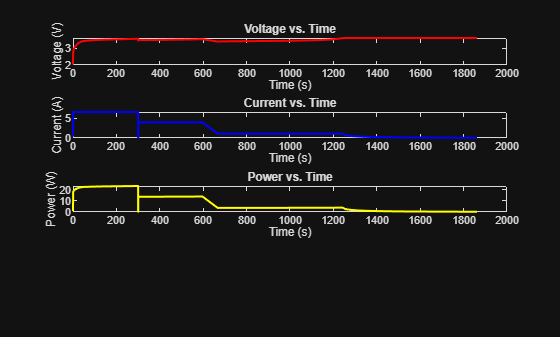

% Insert your code in the spaces below (or make use of helper functions and
% indicate where they can be found). Ensure your code is well-documented.

% STEP 1
% Create a figure handle and initialize the first subplot. Plot voltage vs.
% time.
fig = figure;

subplot1 = subplot(4, 1, 1);
plot(subplot1, time, voltage, '-r', 'LineWidth', 1.5);
xlabel(subplot1, "Time (s)");
ylabel(subplot1, "Voltage (V)");
title("Voltage vs. Time")

% STEP 2
% Use a second subplot to plot current vs. time.
current = cycleData.Current;

subplot2 = subplot(4, 1, 2);
plot(subplot2, time, current, '-b', 'LineWidth', 1.5);
xlabel(subplot2, "Time (s)");
ylabel(subplot2, "Current (A)");
title("Current vs. Time")

% STEP 3
% Use a third subplot to plot power vs time.
% Hint: P = I * V where I is current in amps. You will first
% need to compute power before you can create this plot.
power = current .* voltage;

subplot3 = subplot(4, 1, 3);
plot(subplot3, time, power, '-y', 'LineWidth', 1.5);
xlabel(subplot3, "Time (s)");
ylabel(subplot3, "Power (W)");
title("Power vs. Time")

## Task 3: Compute analytical results

To get started on using MATLAB for numerical integration and differentiation, start with this [doc page](https://www.mathworks.com/help/matlab/numerical-integration-and-differentiation.html?s_tid=CRUX_lftnav).

- Conduct a rate-of-change analysis by computing the derivative at key intervals in the voltage data

- Compute the time required to reach 80% and 100% charge

- Compute the total energy delivered to the battery by using integration to calculate the area under the power-time curve.

- Estimate the resistive energy loss

- Save the results to a summary table.

% STEP 1: Compute the rate of voltage change at different key time
% intervals. This helps you mathematically characterize the battery's
% charging profile and is more reliable than simply eyeballing the voltage
% vs. time plot. 

% initial calculation, take derivative of voltage with respect to time (dV/dt)
voltageChange = diff(voltage) ./ diff(time);

% interval between t = 0s and t = 100s (this is just a test, i'm still figuring out matlab -Cris)
timeStart = find(time >= 0, 1);
timeEnd   = find(time >= 100, 1);
firstInterval = (voltage(timeEnd) - voltage(timeStart)) / (time(timeEnd) - time(timeStart));

fprintf('First interval output (t = %d to %.2f s): dV/dt = %.4f V/s\n', time(idx_start), time(idx_end), firstInterval);

First interval output (t = 0 to 104.56 s): dV/dt = 0.0138 V/s



% Intervals (Based on Changes in Voltage vs. Time Graph) - Aren

interval1 = time >= 0 & time <= 100;
interval2 = time > 100 & time <= 300;
interval3 = time > 300 & time <= 600;
interval4 = time > 600 & time <= 1250;
interval5 = time > 1250 & time <= 1800;

% 0-100 s

time1 = time(interval1);
voltage1 = voltage(interval1);
dVdt1 = diff(voltage1) ./ diff(time1);
avg1 = mean(dVdt1);

% 100-300 s

time2 = time(interval2);
voltage2 = voltage(interval2);
dVdt2 = diff(voltage2) ./ diff(time2);
avg2 = mean(dVdt2);

% 300-600 s

time3 = time(interval3);
voltage3 = voltage(interval3);
dVdt3 = diff(voltage3) ./ diff(time3);
avg3 = mean(dVdt3);

% 600-1250 s

time4 = time(interval4);
voltage4 = voltage(interval4);
dVdt4 = diff(voltage4) ./ diff(time4);
avg4 = mean(dVdt4);

% 1250-1800 s

time5 = time(interval5);
voltage5 = voltage(interval5);
dVdt5 = diff(voltage5) ./ diff(time5);
avg5 = mean(dVdt5);

% dVdt Print

fprintf("Average rate of voltage change from 0-100 seconds: %.4f V/s \n", avg1)
fprintf("Average rate of voltage change from 100-300 seconds: %.4f V/s \n", avg2)
fprintf("Average rate of voltage change from 300-600 seconds: %.4f V/s \n", avg3)
fprintf("Average rate of voltage change from 600-1250 seconds: %.4f V/s \n", avg4)
fprintf("Average rate of voltage change from 1250-1800 seconds: %.4f V/s \n", avg5)

% Optional: plot the points of notable transitions in charging dynamics in
% the voltage vs. time plot generated above
% Hint: explore using the gradient function

% STEP 2: Compute the time required to reach 80% charge and 100% charge

% Time to Reach 80% Charge

v80 = 0.80 * max(voltage);

indexV80 = find(voltage >= v80, 1);

time80 = time(indexV80);

% Time to Reach 100% Charge

[maxVoltage, timeMaxVoltage] = max(voltage);

time100 = time(timeMaxVoltage);

% Printing

fprintf("Time to reach 80 Percent Charge: %.3f seconds \n", time80)
fprintf("Time to reach 100 Percent Charge: %.3f seconds \n", time100)

% STEP 3: Use integration to calculate the area under the power-time curve.
% This represents the total energy delivered to the battery during charging.
% Hint: explore using the trapz function

totalEnergy = trapz(time, power);

fprintf("Total Energy Delivered to the Battery: %.3f Joules \n", totalEnergy)

% STEP 4: Estimate the resistive energy loss. 
% Hint: use Joule's heating formula (P = I^2 * R) to estimate power loss in
% watts. The energy loss is given as E = P * t, where t is time in seconds
% and energy is in joules.

% Calculate Resistance with Ohm's Law

R = mean(voltage ./ current);

% Calculate Power with Joule's Heating Formula

powerLoss = current.^2 .* R;
avgPowerLoss = mean(powerLoss);

% Calculate Energy Loss

energyLoss = avgPowerLoss .* (time(end) - time(1));

% Printing

fprintf("Average Power Loss: %.3 Watts \n", avgPowerLoss)
fprintf("Resistive Energy Loss: %.3 Joules \n", energyLoss)

% STEP 5: Save results to a summary table. Display the table.

table(avg1, avg2, avg3, avg4, avg5, time80, time100, totalEnergy, avgPowerLoss, energyLoss)



## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning (for example, why would engineers want to compute the analytical results in Task 3?):

What are some limitations of your work?

What are practical next steps?